Example 1:

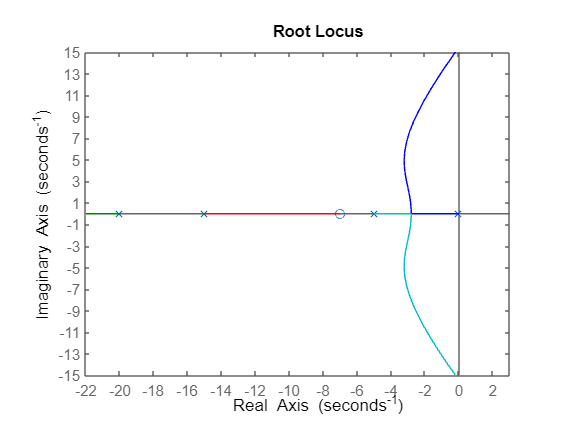

num = [1 7];
den = conv(conv([1 0],[1 5]),conv([1 15],[1 20]));
sys = tf(num, den);
rlocus(sys)
axis([-22 3 -15 15])
xticks(-22:2:3)
yticks(-15:2:15)

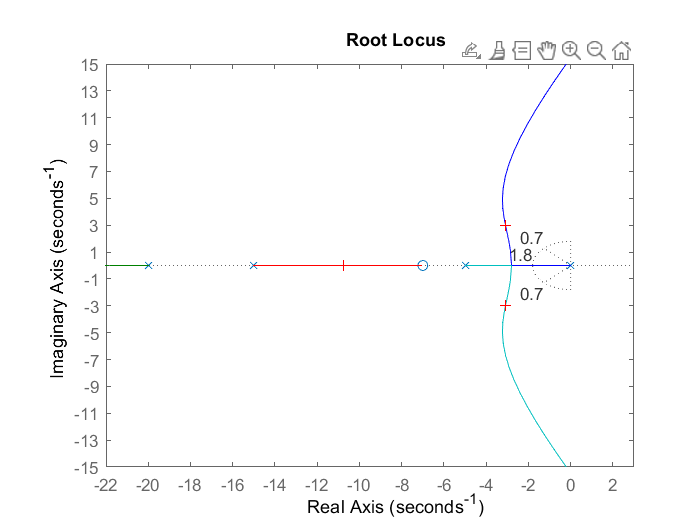

Select a point in the graphics window


selected_point = -3.0843 + 2.9777i

k = 650.9403

poles =  -23.0963 + 0.0000i
 -10.7368 + 0.0000i
  -3.0834 + 2.9778i
  -3.0834 - 2.9778i


zeta=0.7; 
Wn=1.8; 
sgrid(zeta, Wn)
[k, poles] = rlocfind(sys)

sys_cl = feedback(k*sys,1)

sys_cl =
 
              665.9 s + 4661
  --------------------------------------
  s^4 + 40 s^3 + 475 s^2 + 2166 s + 4661
 
Continuous-time transfer function.
Model Properties


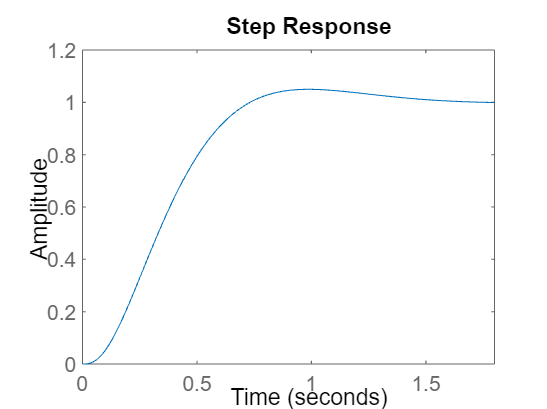

step(sys_cl)

info = stepinfo(sys_cl);
disp(info);

         RiseTime: 0.4578
    TransientTime: 1.3723
     SettlingTime: 1.3723
      SettlingMin: 0.9041
      SettlingMax: 1.0498
        Overshoot: 4.9799
       Undershoot: 0
             Peak: 1.0498
         PeakTime: 0.9840



A Real-time Example: Cruise Control Problem Using Root Locus Method

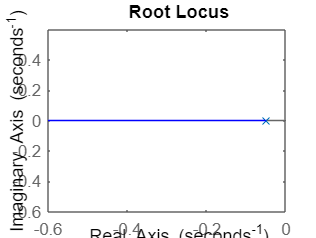

m=1000; 
b=50; 
u=10; 
num=[1]; 
den=[m b]; 
cruise=tf(num,den); 
rlocus(cruise)   
axis([-0.6 0 -0.6 0.6]);

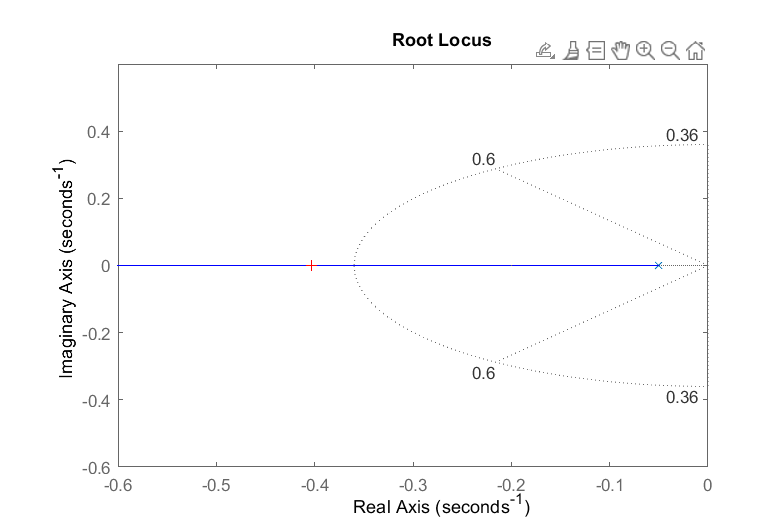

Select a point in the graphics window


selected_point = -0.4032

Kp = 353.2203

poles = -0.4032

zeta=0.6; 
Wn=0.36; 
sgrid(zeta, Wn)
[Kp, poles]=rlocfind(cruise)

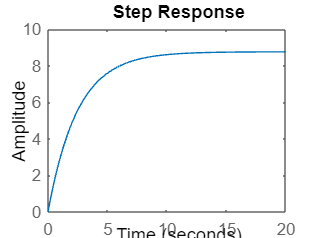

sys_cl=feedback(Kp*cruise,1); 
t=0:0.1:20; 
step(u*sys_cl,t) 
axis ([0 20 0 10])

info = stepinfo(sys_cl);
disp(info);

         RiseTime: 5.4486
    TransientTime: 9.7021
     SettlingTime: 9.7021
      SettlingMin: 0.7923
      SettlingMax: 0.8754
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8754
         PeakTime: 18.1594



to eleminate steady-state error:

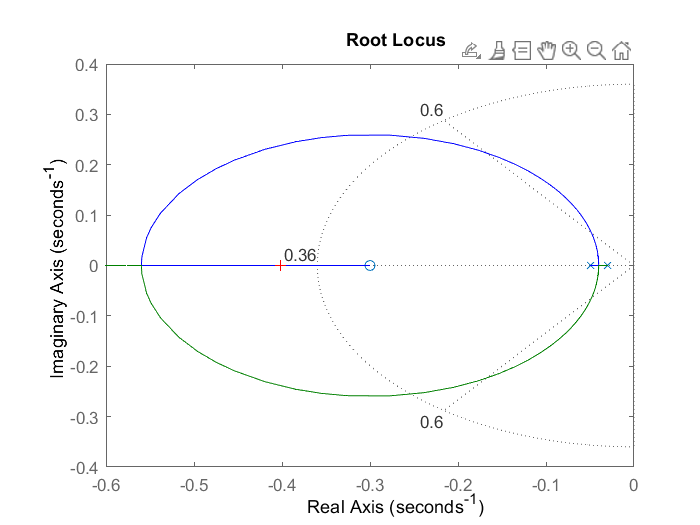

Select a point in the graphics window


selected_point = -0.4017 - 0.0020i

Zo=0.3; 
Po=0.03; 
contr=tf([1 Zo],[1 Po]); 
rlocus(contr*cruise); 
axis([-0.6 0 -0.4 0.4]) 
sgrid(0.6,0.36); 
[Kp, poles]=rlocfind(contr*cruise);

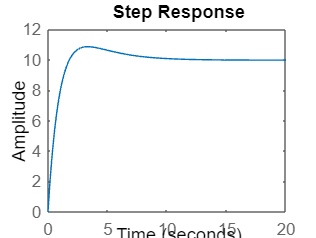

sys_cl=feedback(Kp*contr*cruise,1); 
t=0:0.1:20; 
step(u*sys_cl,t) 
axis ([0 20 0 12])

info = stepinfo(sys_cl);
disp(info);

         RiseTime: 1.2431
    TransientTime: 8.3253
     SettlingTime: 8.3253
      SettlingMin: 0.9006
      SettlingMax: 1.0845
        Overshoot: 8.8708
       Undershoot: 0
             Peak: 1.0845
         PeakTime: 3.3459



Hometask 1:

J = 0.01 + power(( 2108001) ,-6);
b = 0.1 + power((2108001) ,-6);
K = (0.01 + 0.2108001);
R = 1; 
L = (0.5 + 2108001);

num = K; 
den = [(J*L) ((J*R) + (L*b)) ((b*R) + K^2)]; 
motor = tf(num, den)

motor =
 
                0.2208
  ----------------------------------
  2.108e04 s^2 + 2.108e05 s + 0.1488
 
Continuous-time transfer function.
Model Properties


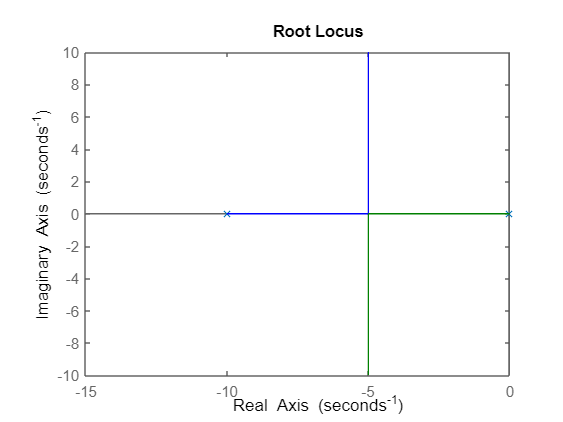

rlocus(motor)
axis([-15 0 -10 10])

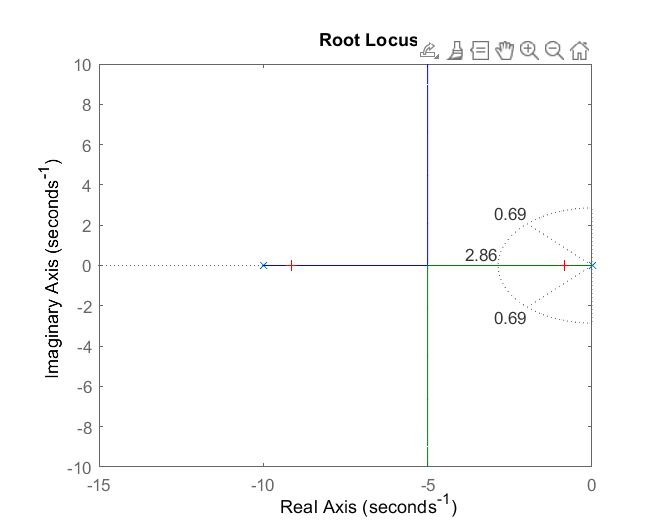

Select a point in the graphics window


selected_point = -0.8063 + 0.2481i

zeta = 0.69;
wn = 2.857;
sgrid(zeta,wn)
[Kp, poles]=rlocfind(motor);

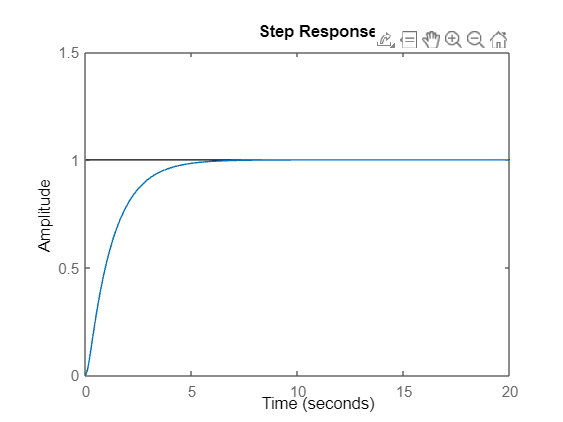

motor_cl=feedback(Kp*motor,1); 
t=0:0.1:20; 
step(u*motor_cl,t);
axis ([0 20 0 1.5]);

info = stepinfo(sys_cl);
disp(info);

         RiseTime: 2.6095
    TransientTime: 4.7294
     SettlingTime: 4.7294
      SettlingMin: 0.9040
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 8.6374



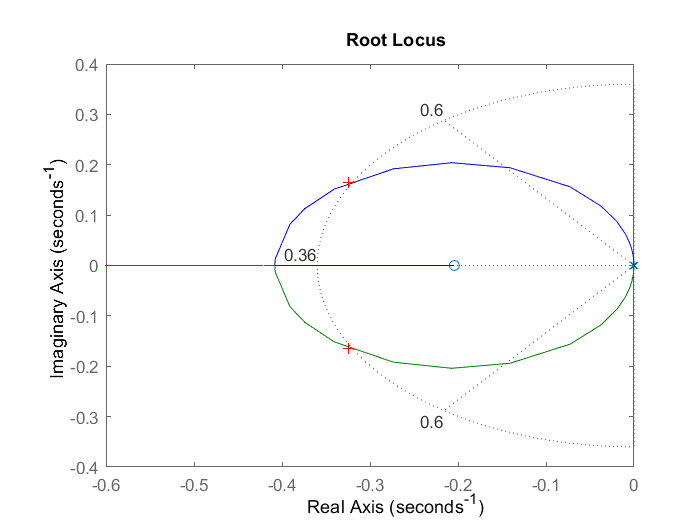

Select a point in the graphics window


selected_point = -0.3199 + 0.1588i

Ki = Kp / 5; 
Kd = Kp / 10; 
contr = tf([Kd Kp Ki],[1 0]);  
rlocus(contr*motor); 
axis([-0.6 0 -0.4 0.4]) 
sgrid(0.6,0.36); 
[Kp, poles]=rlocfind(contr*motor);

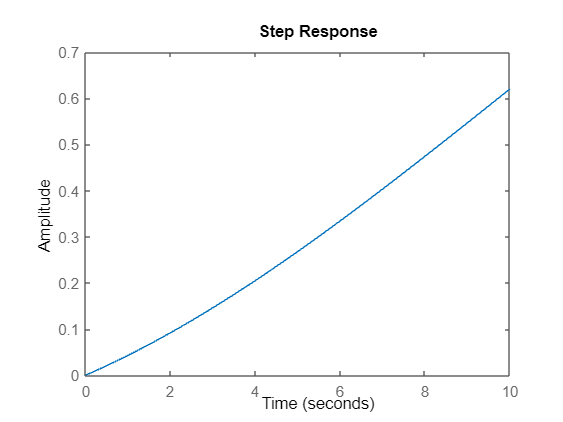

sys_cl = feedback(contr*motor,1); 
t = 0:0.01:10; 
step(sys_cl,t)

info = stepinfo(sys_cl);
disp(info);

         RiseTime: 0.9751
    TransientTime: 9.3545
     SettlingTime: 9.3545
      SettlingMin: 0.9162
      SettlingMax: 1.0775
        Overshoot: 7.7542
       Undershoot: 0
             Peak: 1.0775
         PeakTime: 2.8880

